# Test Road Detection Try 1

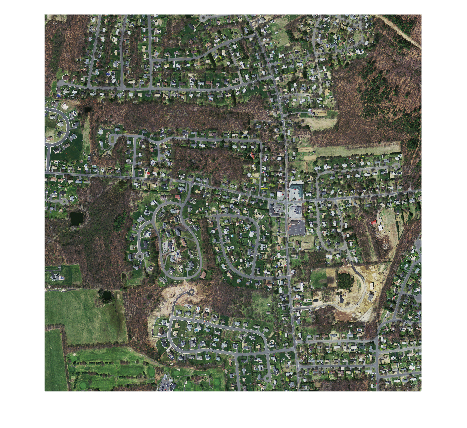

clf
im1 = imread('../images/img-9.png');
imshow(im1)

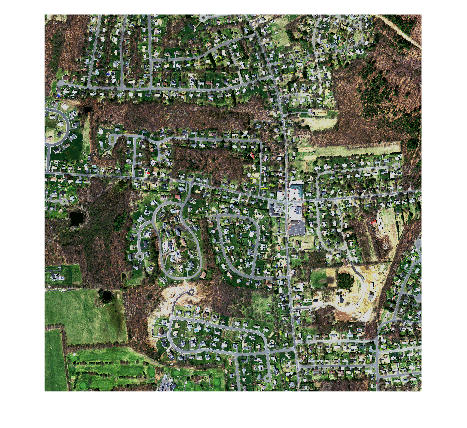


% higher contrast
im1 = im1 * 1.5 - 40;
imshow(im1)

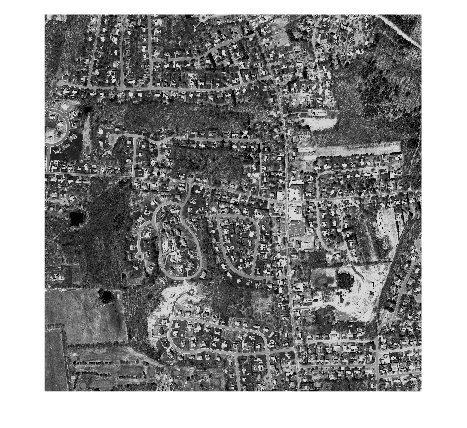


% just grayscale
im1_gray = rgb2gray(im1);
imshow(im1_gray)


% enhance contrast
im1 = imadjust(im1_gray)

im1 = 1500×1500 uint8 矩阵
   135    88    83   103    71    99    89   126   168   178   248   254   255   255   255   255   254   253   249   239   251   253   208   250   249   249   201   164   163   156   190   140   147   155   141    89   100    60   110   146    98   169   140   100   114   131   152   153   156   126
   123    81    99    81    79    87    79   129   156   161   254   255   255   255   251   251   255   250   219   250   250   250   250   249   249   250   207   186   180   191   191   169    92   110   144   131    95    75    73    82    83   121   199   132   100    79    85    97   134   150
   118    58    89    70    75    79   108   134   170   173   255   255   255   255   250   255   255   132   250   250   249   248   251   250   249   251   213   186   149   192   141   157   168   131   127    60    58    99    95   104   102   120   145   110    80    68    44    58    56   225
   122    76    95    77    86   103   102   150   189   191   255   255

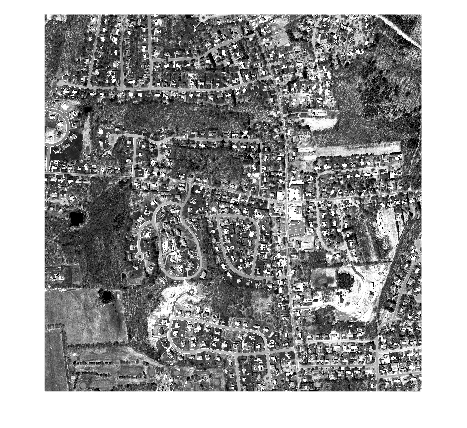

imshow(im1)

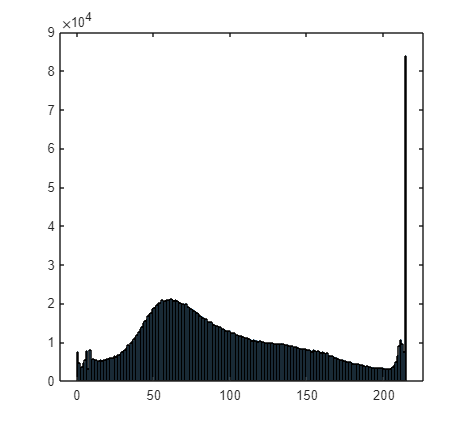

% binarize
histogram(im1_gray)

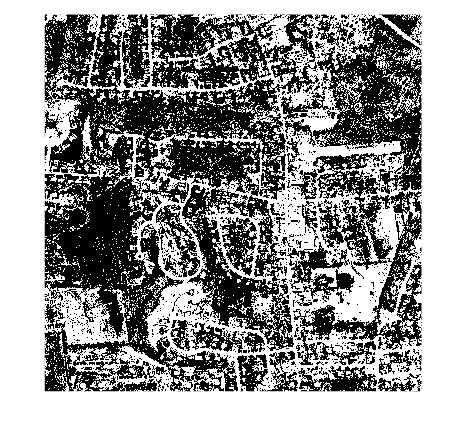

BW = imbinarize(im1_gray,100/256);
imshow(BW)

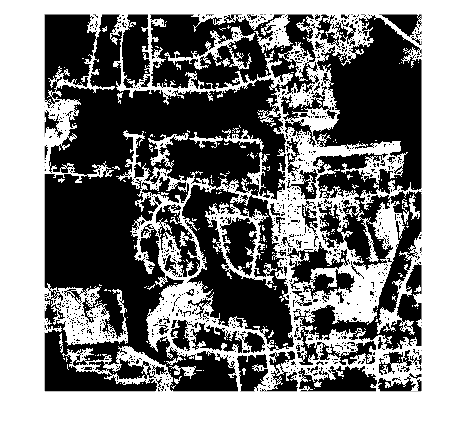


% remove noise
BW2 = bwareafilt(BW,4);
imshow(BW2)

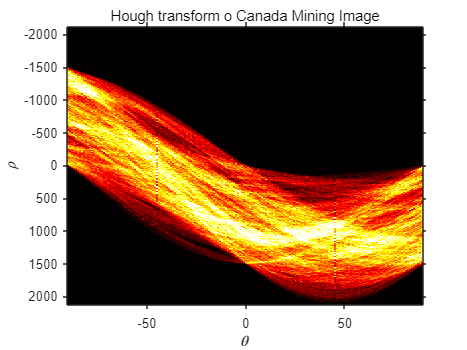


% hough line detection
bw1 = edge(BW2,'canny');
[H,T,R] = hough(bw1);

% plot hough graph
figure;
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform o Canada Mining Image');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

P  = houghpeaks(H,20);
%P = houghpeaks(H, 10, 'Threshold', 0.3 * max(H(:)));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

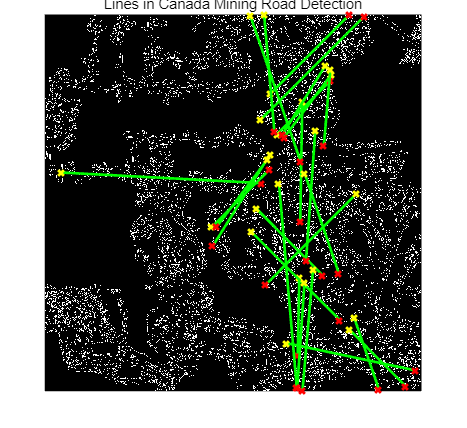


figure;
lines = houghlines(bw1,T,R,P,'FillGap', 40, 'MinLength',300);
imshow(bw1), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
title('Lines in Canada Mining Road Detection')